clear all;
% Loading workspace variables
run('load_params_estimatedValues.m');

# PID parameters (Bode method)

% Semplified plant
simp_model.P

ans =
 
        77.86
  -----------------
  0.4154 s^2 + 14 s
 
Continuous-time transfer function.



[kp, ki, kd] = BodMet(10*pi,60,simp_model);
kp

kp = 7.5244

ki

ki = 94.0379

kd

kd = 0.1505

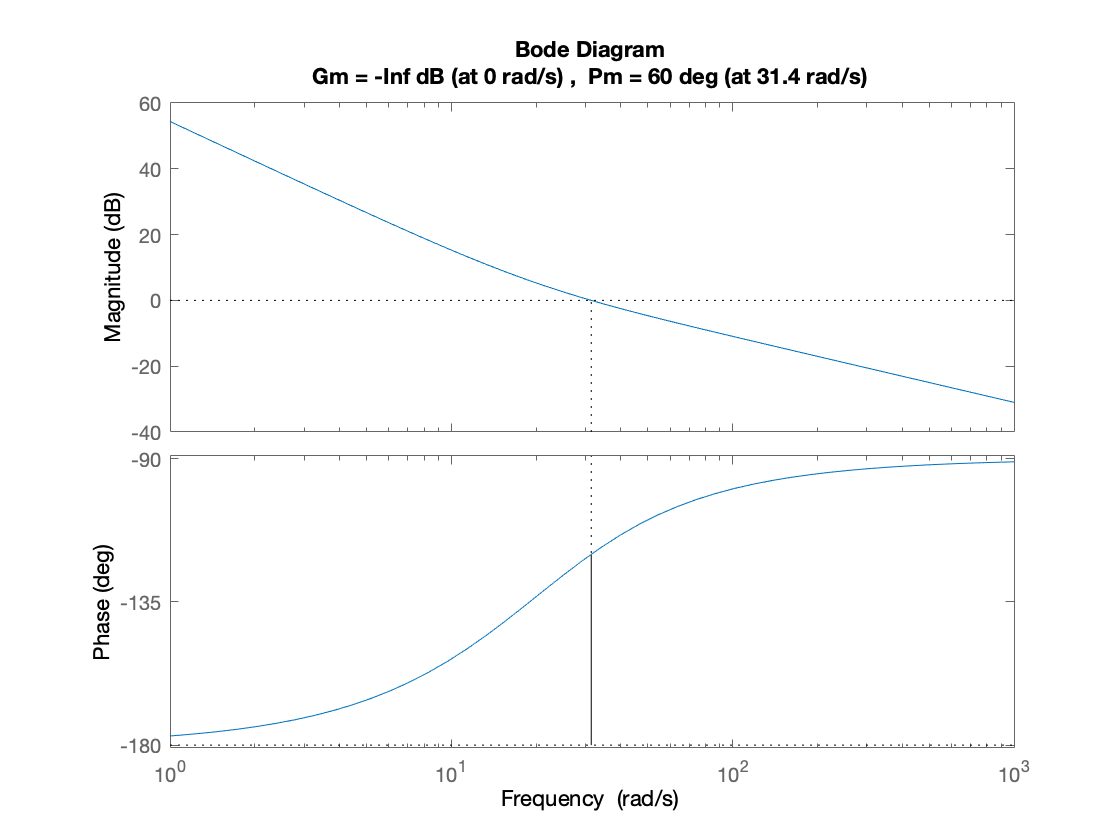

s = tf('s');
bod_met.controller = kp + ki/s + kd*s/(0.000*s+1); % Controller
margin(bod_met.controller*simp_model.P)

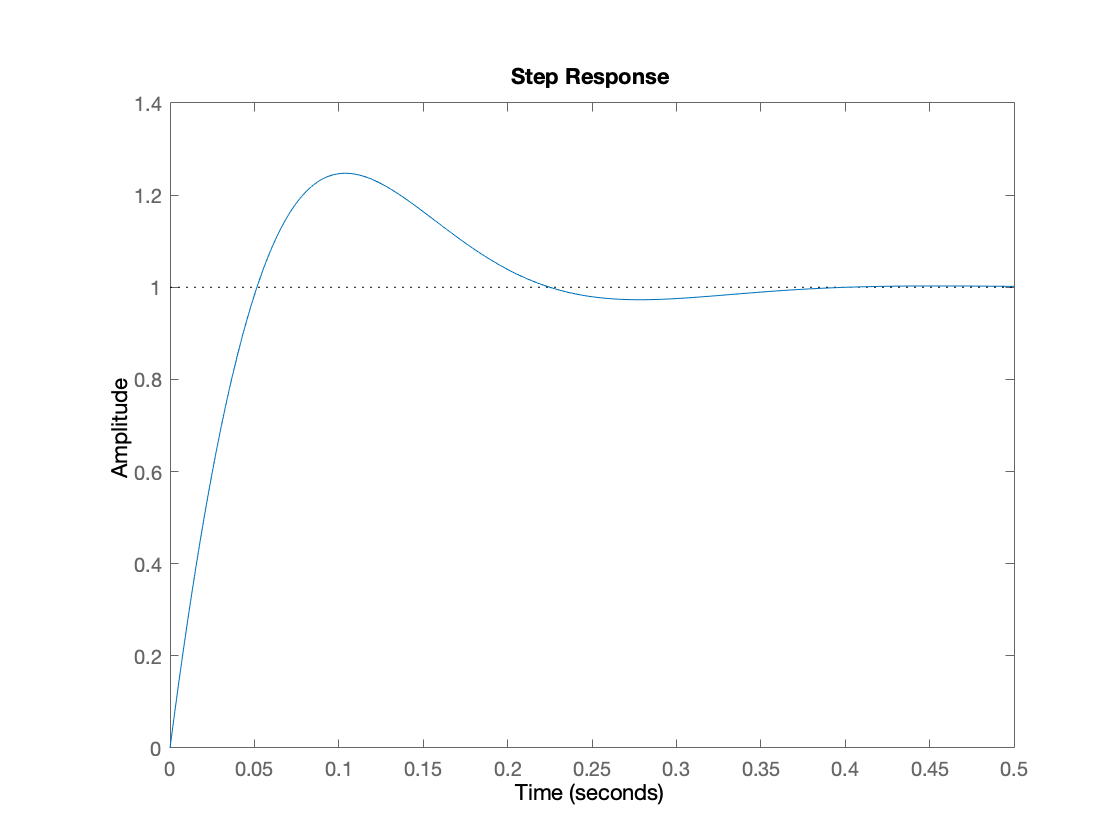

bod_met.W = feedback(bod_met.controller*simp_model.P,1); % Closed loop TF
charac.tr = stepinfo(bod_met.W).RiseTime;
charac.ts = stepinfo(bod_met.W).SettlingTime;
charac.mp = stepinfo(bod_met.W).Overshoot;
step(bod_met.W)

charac

charac = struct with fields:
    tr: 0.0397
    ts: 0.3176
    mp: 24.7552


# 2.1 Position PID–control improvements

## 1.  Anti-Windup

K_w = 2.5; % Trial & Error

#### Simulation results

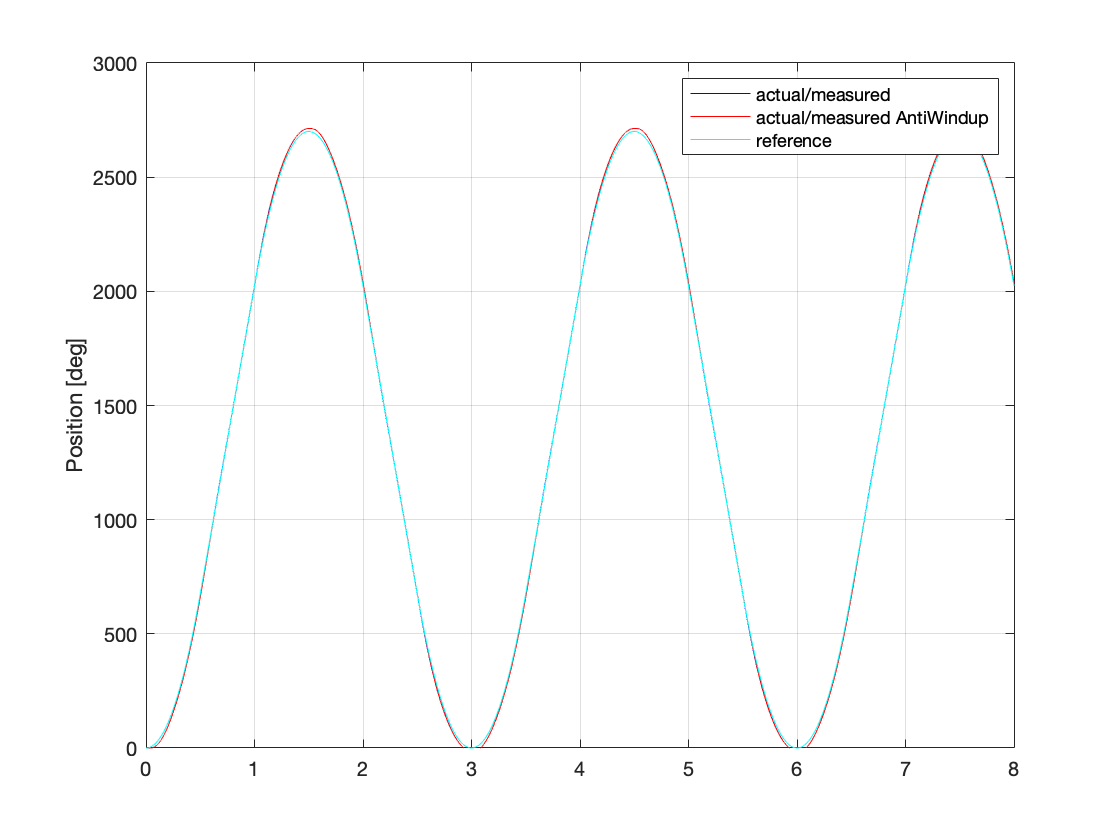

% Open Simulink model
open_system('Simulink/AntiWindup_FF.slx');

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '8');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','1'); % Anti-Windup ON
set_param('AntiWindup_FF/Enable Feed-forward1','Value','0');

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
AW.t = simres.time; % time vector                        
AW.thl = simres.signals(1).values(:,1); % load position
AW.thl_AW = simres.signals(1).values(:,2); % load position (AW)
AW.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(1);
plot(AW.t, AW.thl, 'b-');
hold on;
plot(AW.t, AW.thl_AW, 'r-');
hold on;
plot(AW.t, AW.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([0,3000]);
legend('actual/measured', 'actual/measured AntiWindup', 'reference');

## 2.  Feed-Forward

#### Simulation results

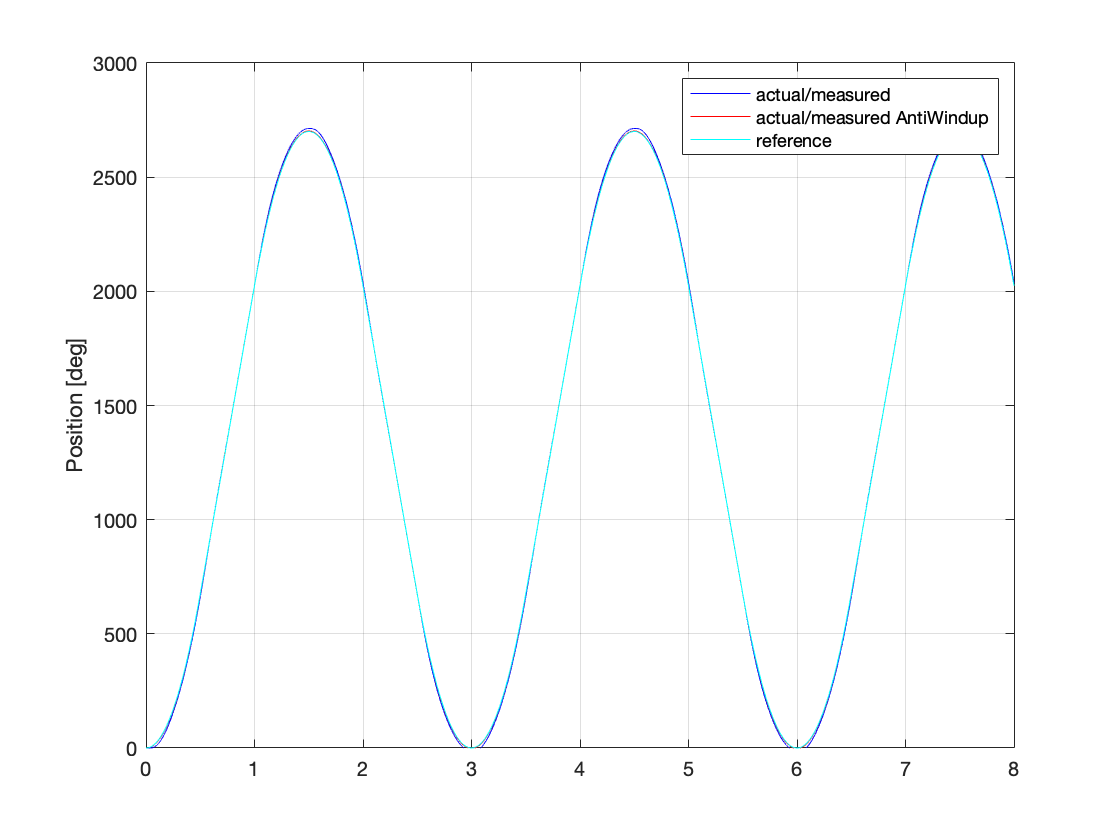

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '8');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward1','Value','1'); % Feed-Forward ON

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
FF.t = simres.time; % time vector                        
FF.thl = simres.signals(1).values(:,1); % load position
FF.thl_FF = simres.signals(1).values(:,2); % load position (AW)
FF.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(2);
plot(FF.t, FF.thl, 'b-');
hold on;
plot(FF.t, FF.thl_FF, 'r-');
hold on;
plot(FF.t, FF.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([0,3000]);
legend('actual/measured', 'actual/measured AntiWindup', 'reference');

# 2.2 Position state–space control design

## 1.  $\bf{State-Space\  Nominal \ Control}$

% State-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Nx, Nu
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;1]);
nominal.N_x = nominal.X(1:2,:);
nominal.N_u = nominal.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
nominal.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
nominal.wn = 3/(nominal.delta*ts);
nominal.Tnum = [nominal.wn^2];
nominal.Tden = [1 2*nominal.delta*nominal.wn nominal.wn^2];
nominal.T = tf(nominal.Tnum,nominal.Tden); % Dominant closed–loop dynamics approximation

% Pole placement
nominal.p1 = -nominal.delta*nominal.wn + 1i*nominal.wn*sqrt(1-nominal.delta^2);
nominal.p2 = conj(nominal.p1);
nominal.poles = [nominal.p1 nominal.p2];
nominal.K = place(state_space.A,state_space.B,nominal.poles);

#### Simulation results 40°

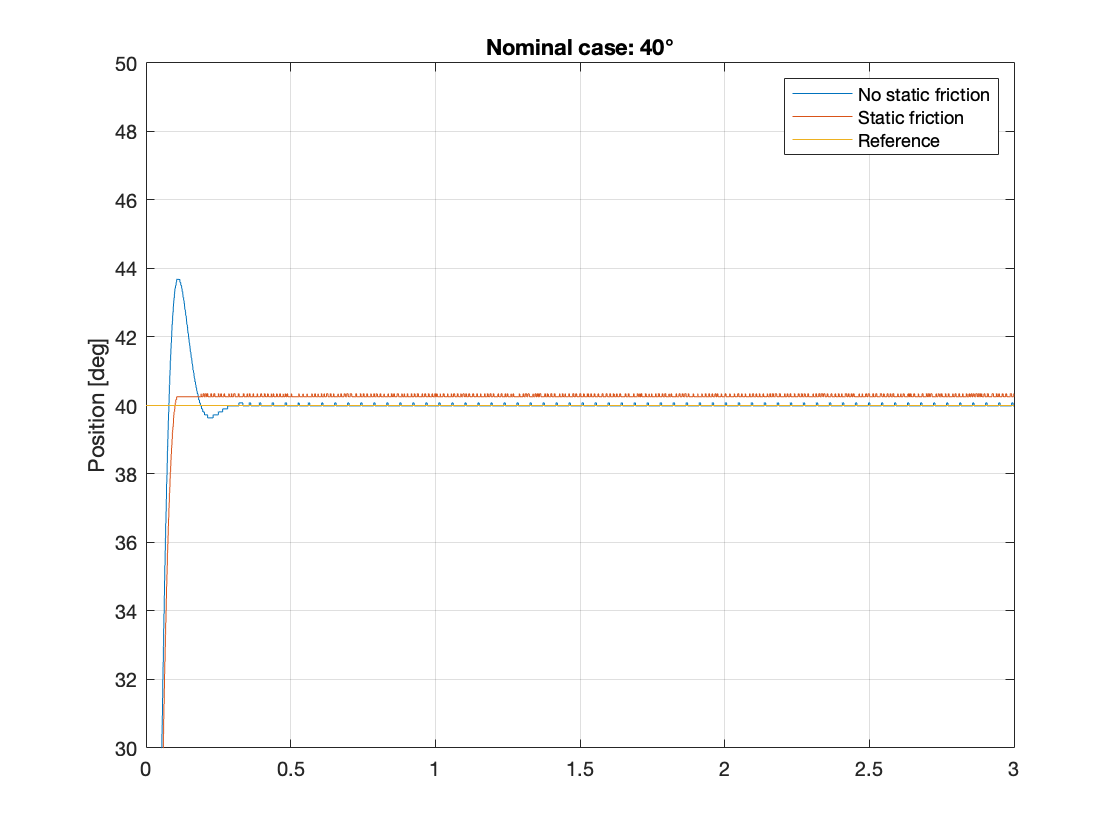

% Open Simulink model
open_system('Simulink/SS_Nominal_Integral.slx');

% Set parameters
set_param('SS_Nominal_Integral', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','40');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','40');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','nominal.K');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','nominal.K');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(3);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([30,50]);
title('Nominal case: 40°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 70°

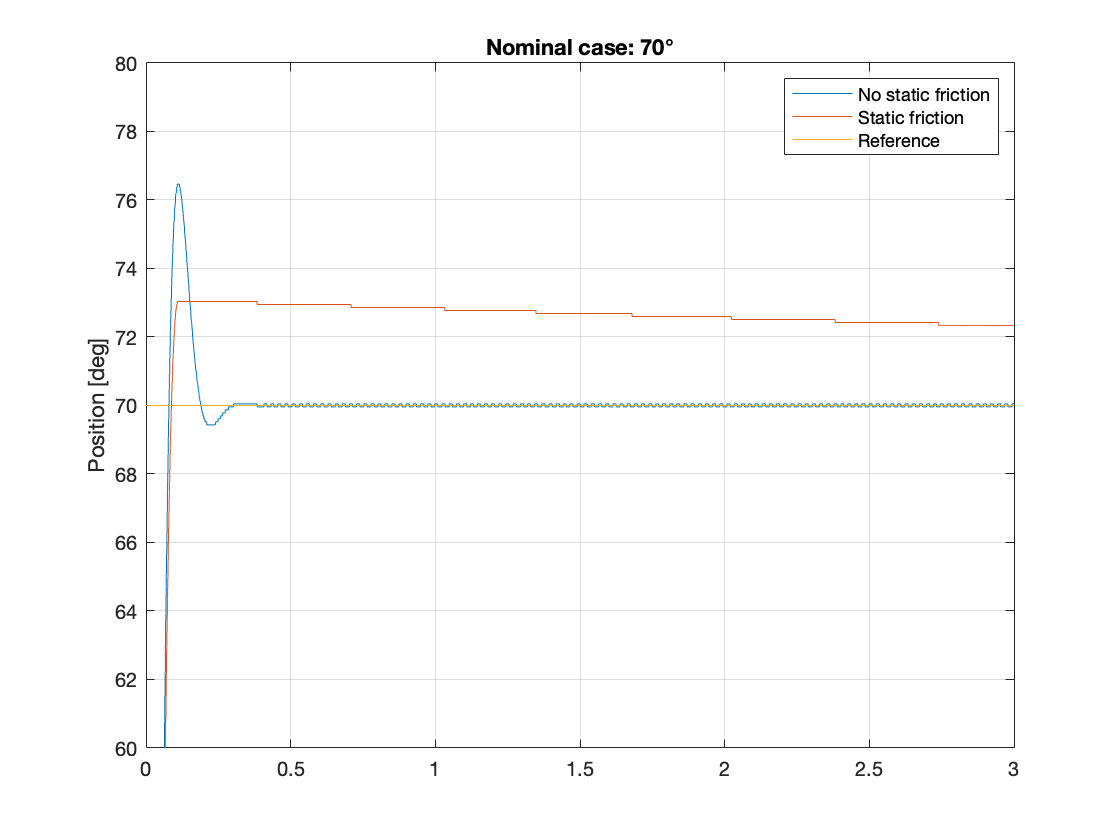

% Set parameters
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','70');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','70');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','nominal.K');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','nominal.K');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(4);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([60,80]);
title('Nominal case: 70°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 120°

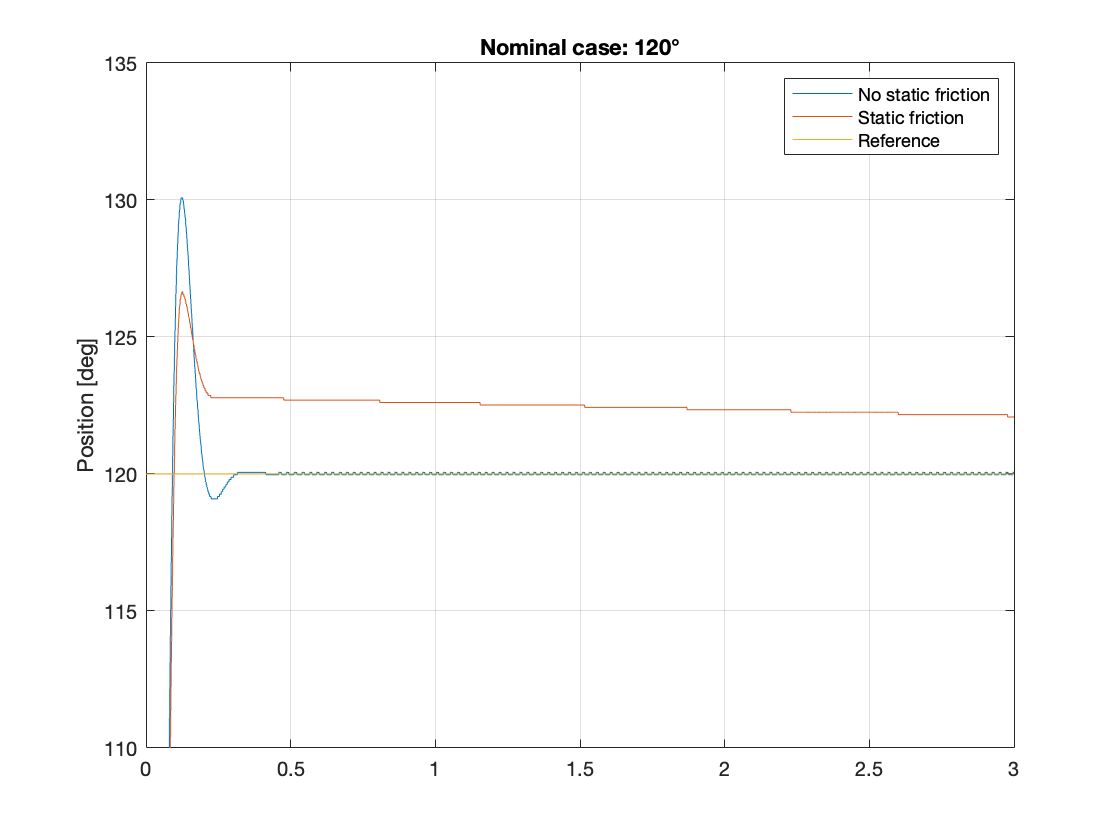

% Set parameters
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','120');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','120');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','0'); % Nominal action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','0'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','nominal.K');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','nominal.K');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(5);
plot(nominal.t, nominal.thl_nsf);
hold on;
plot(nominal.t, nominal.thl_sf);
hold on;
plot(nominal.t, nominal.thl_Ref);
ylabel('Position [deg]');
grid on;
ylim([110,135]);
title('Nominal case: 120°');
legend('No static friction', 'Static friction', 'Reference');

## 2.  $\bf{State-Space\  Robust \ Control \ (Integral \ 
 action)}$

% Augmented state-space
robust.Ae = [0 state_space.C;[0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Real and imaginary parts of the eigenvalues in (6) (in the assignment 1)
robust.sigma = -nominal.delta*nominal.wn;
robust.wd = nominal.wn*sqrt(1-nominal.delta^2);
% Pole placement
robust.poles1 = [robust.sigma + 1i*robust.wd, robust.sigma - 1i*robust.wd, robust.sigma];
robust.poles2 = [robust.sigma, robust.sigma, robust.sigma];
robust.poles3 = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 2*robust.sigma];
robust.poles4 = [2*robust.sigma + 1i*robust.wd, 2*robust.sigma - 1i*robust.wd, 3*robust.sigma];

% Ke1
robust.Ke_1 = place(robust.Ae,robust.Be,robust.poles1);
robust.Ki_1 = robust.Ke_1(1);
robust.K_1 = robust.Ke_1(1,2:3);

% Ke2
robust.Ke_2 = acker(robust.Ae,robust.Be,robust.poles2);
robust.Ki_2 = robust.Ke_2(1);
robust.K_2 = robust.Ke_2(1,2:3);

% Ke3
robust.Ke_3 = place(robust.Ae,robust.Be,robust.poles3);
robust.Ki_3 = robust.Ke_3(1);
robust.K_3 = robust.Ke_3(1,2:3);

% Ke4
robust.Ke_4 = place(robust.Ae,robust.Be,robust.poles4);
robust.Ki_4 = robust.Ke_4(1);
robust.K_4 = robust.Ke_4(1,2:3);

### Simulation results 40°

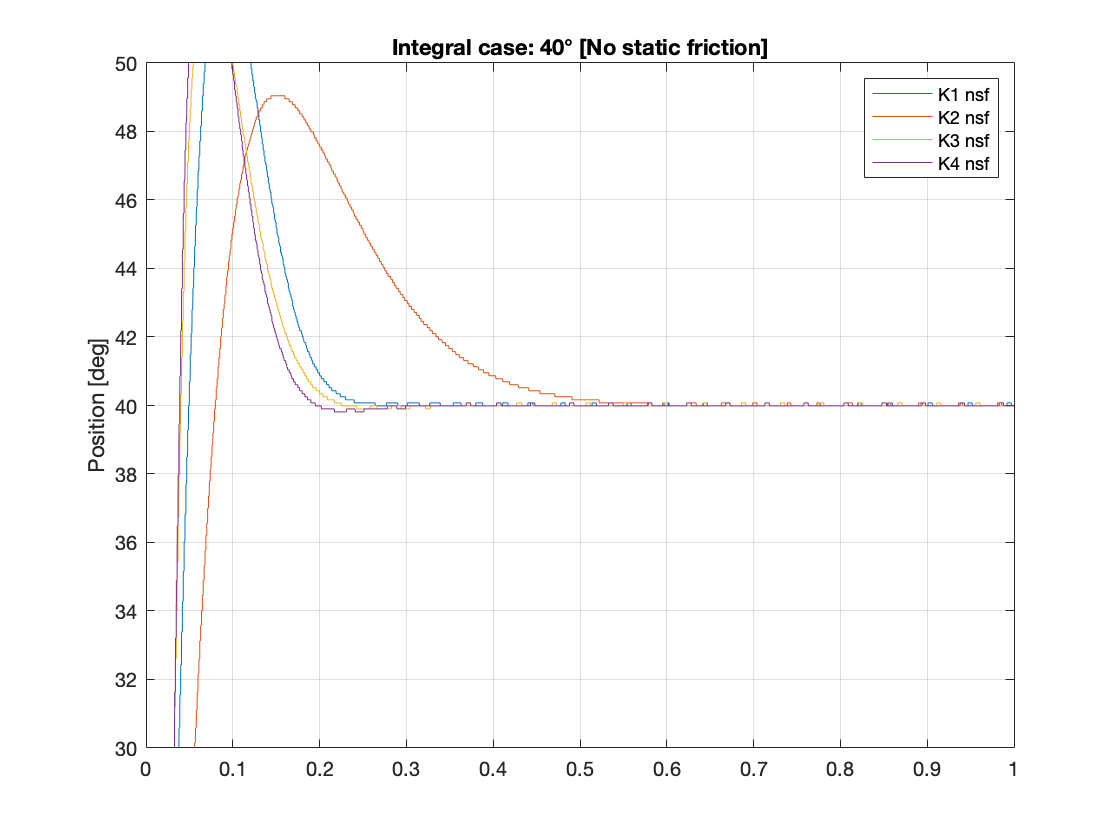

% Set parameters for K1
set_param('SS_Nominal_Integral', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '1');
% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','40');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','40');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_1'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_1'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_1');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_1');
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction


% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results for K1
int_k1.t = simres.time; % time vector                        
int_k1.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k1.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k1.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Set parameters for K2
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_2'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_2');
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_2');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_2'); 

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k2.t = simres.time; % time vector                        
int_k2.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k2.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k2.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Set parameters for K3
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_3'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_3'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_3');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_3'); 

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k3.t = simres.time; % time vector                        
int_k3.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k3.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k3.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Set parameters for K4
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_4'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_4'); 
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_4');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_4');

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k4.t = simres.time; % time vector                        
int_k4.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k4.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k4.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results (NO STATIC FRICTION)
figure(6);
plot(int_k1.t, int_k1.thl_nsf);
hold on;
plot(int_k2.t, int_k2.thl_nsf);
hold on;
grid on;
plot(int_k3.t, int_k3.thl_nsf);
hold on;
plot(int_k4.t, int_k4.thl_nsf);
ylabel('Position [deg]');
ylim([30,50]);
title('Integral case: 40° [No static friction]');
legend('K1 nsf','K2 nsf','K3 nsf','K4 nsf');

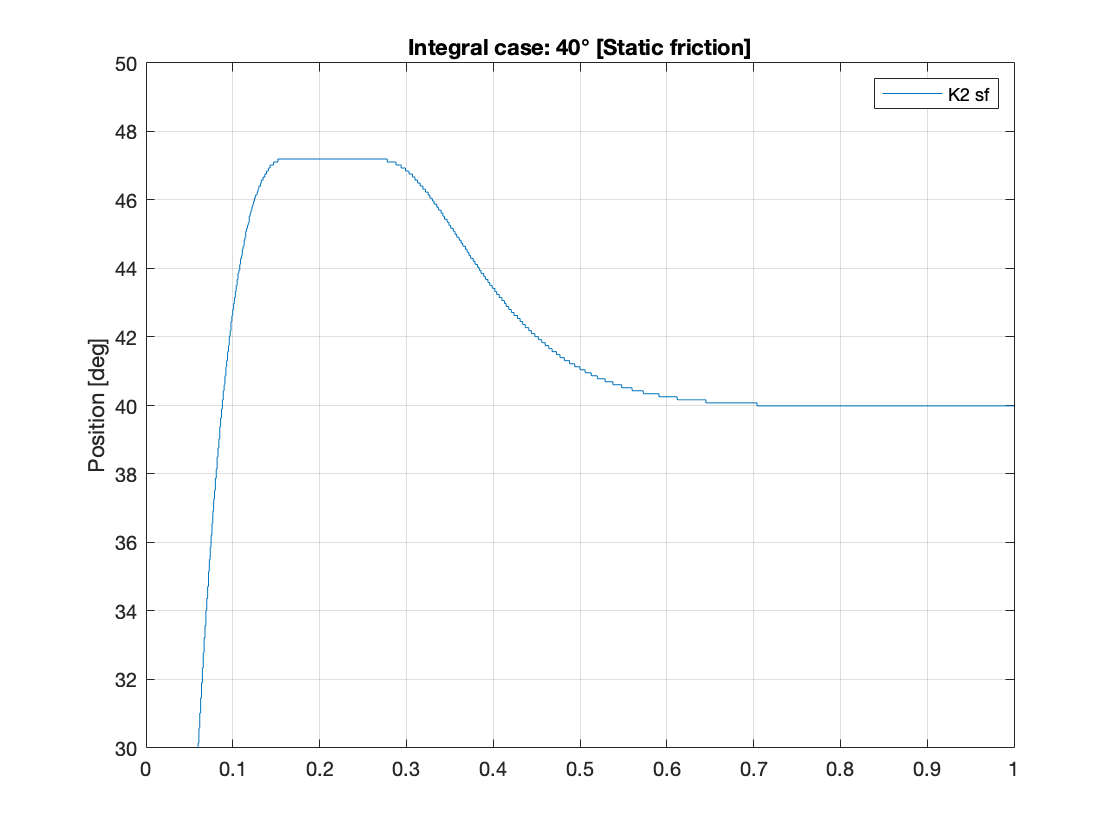

% Plot simulation results (STATIC FRICTION)
figure(7);
plot(int_k2.t, int_k2.thl_sf);
ylabel('Position [deg]');
ylim([30,50]);
grid on;
title('Integral case: 40° [Static friction]');
legend('K2 sf');

### Simulation results 70°

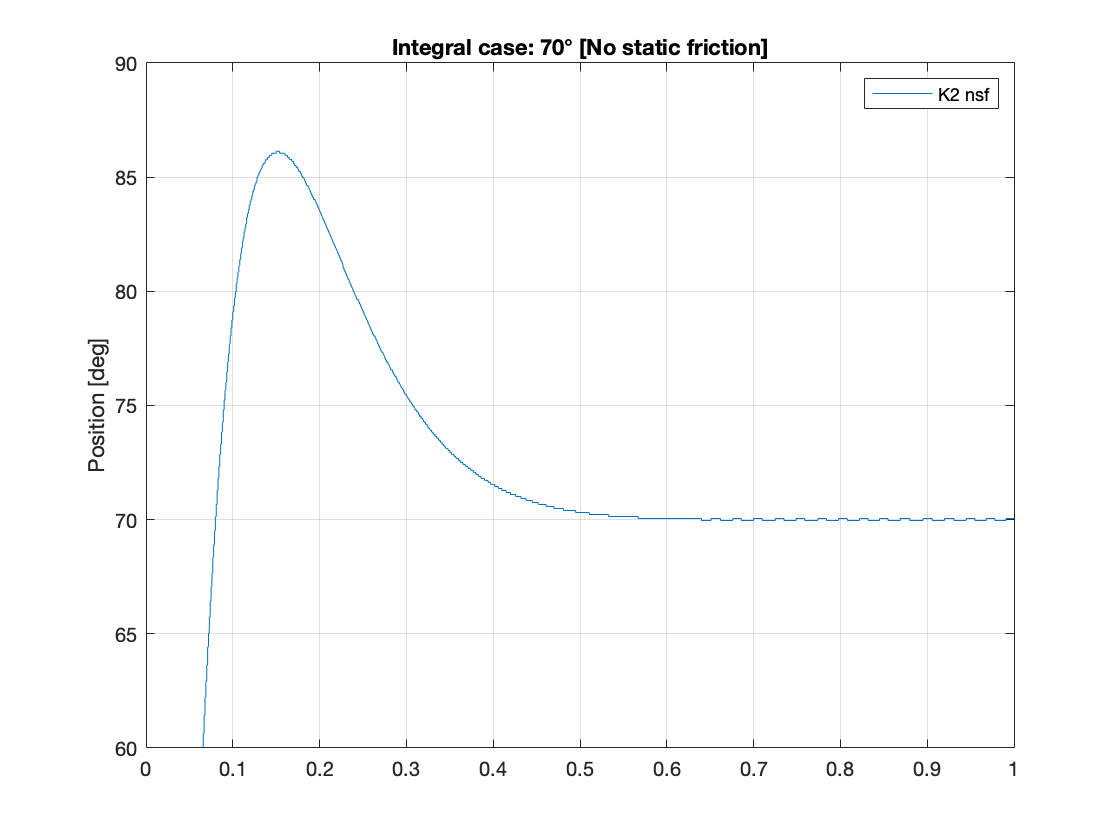

% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','70');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','70');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_2'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_2');
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_2');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_2'); 

% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k2.t = simres.time; % time vector                        
int_k2.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k2.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k2.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results (NO STATIC FRICTION)
figure(8);
plot(int_k2.t, int_k2.thl_nsf);
ylabel('Position [deg]');
ylim([60,90]);
grid on;
title('Integral case: 70° [No static friction]');
legend('K2 nsf');

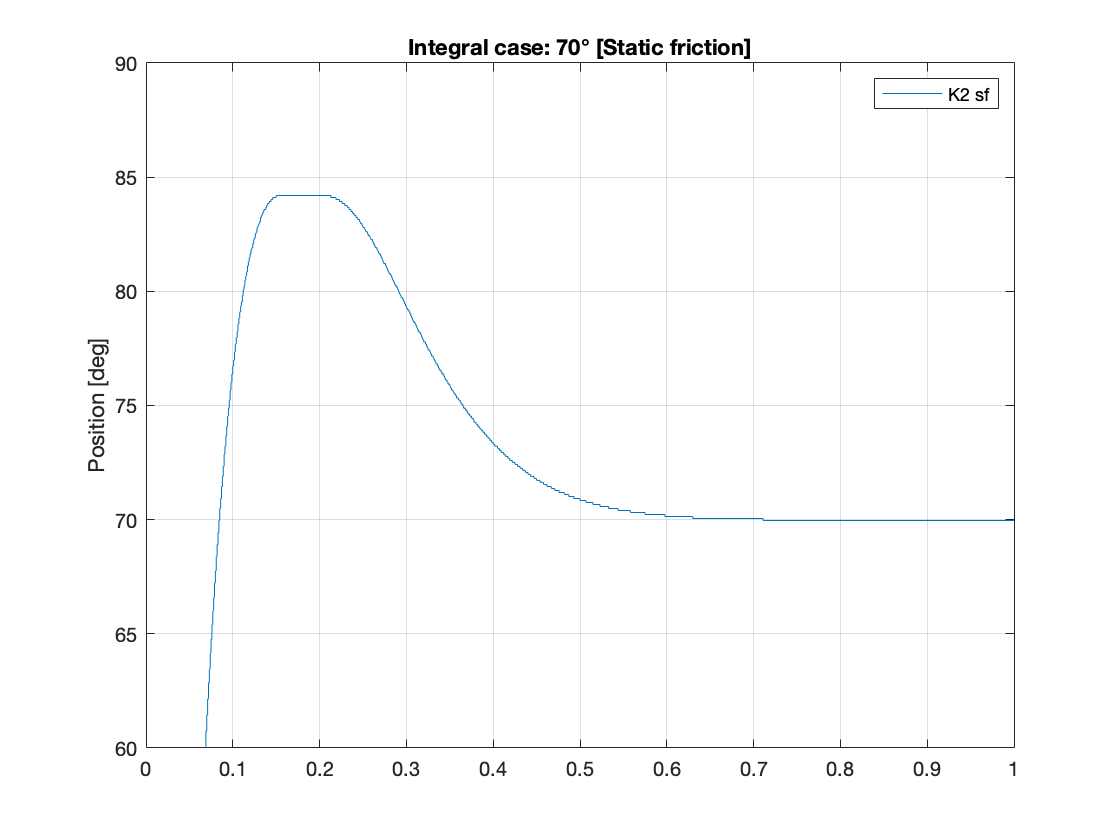


% Plot simulation results (STATIC FRICTION)
figure(9);
plot(int_k2.t, int_k2.thl_sf);
ylabel('Position [deg]');
ylim([60,90]);
grid on;
title('Integral case: 70° [Static friction]');
legend('K2 sf');

#### Simulation results 120°

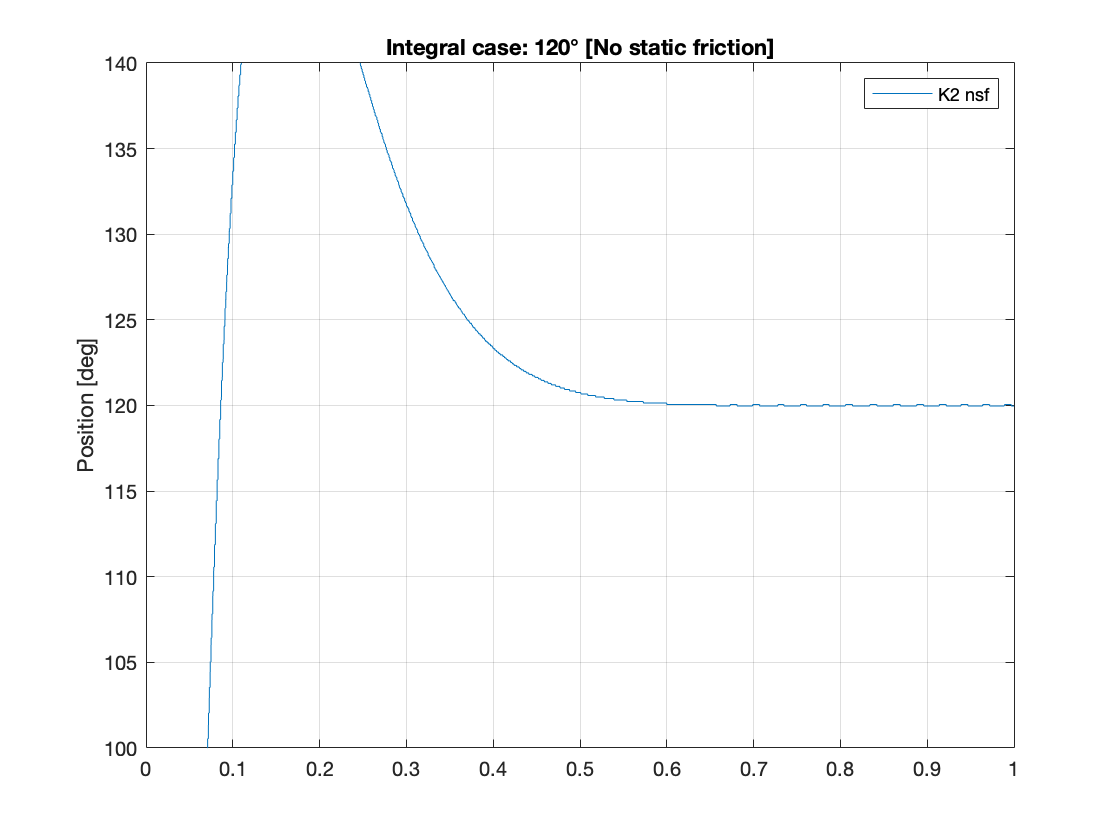

% Ref & Ref1 
set_param('SS_Nominal_Integral/Ref','Time','0','Before','0','After','120');
set_param('SS_Nominal_Integral/Ref1','Time','0','Before','0','After','120');
% State-space Controller
set_param('SS_Nominal_Integral/State-space Controller/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller1/integral','sw','1'); % Integral action ON
set_param('SS_Nominal_Integral/State-space Controller/ki','Gain','robust.Ki_2'); 
set_param('SS_Nominal_Integral/State-space Controller1/ki','Gain','robust.Ki_2');
set_param('SS_Nominal_Integral/State-space Controller/State feedback gain','Gain','robust.K_2');
set_param('SS_Nominal_Integral/State-space Controller1/State feedback gain','Gain','robust.K_2'); 
% DC motor + gearbox
set_param('SS_Nominal_Integral/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Nominal_Integral/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Nominal_Integral');

% Extract simulation results
int_k2.t = simres.time; % time vector                        
int_k2.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
int_k2.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
int_k2.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results (NO STATIC FRICTION)
figure(10);
plot(int_k2.t, int_k2.thl_nsf);
ylabel('Position [deg]');
ylim([100,140]);
grid on;
title('Integral case: 120° [No static friction]');
legend('K2 nsf');

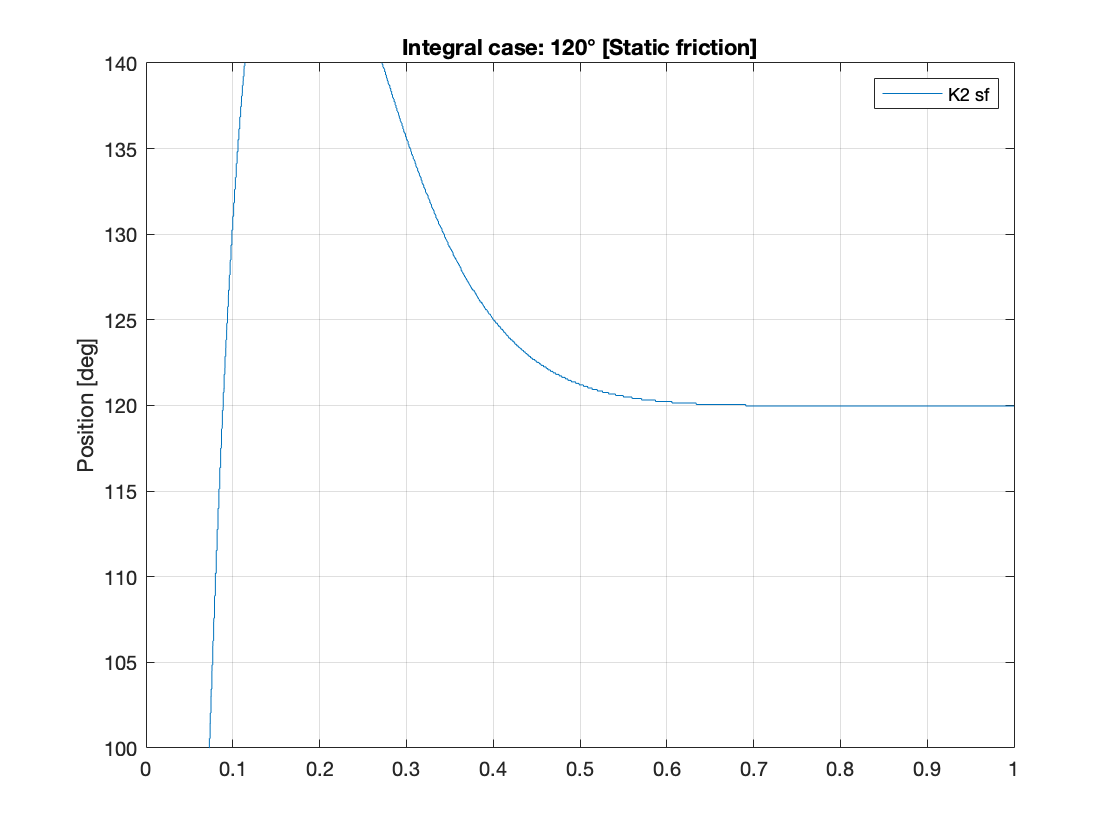


% Plot simulation results (STATIC FRICTION)
figure(11);
plot(int_k2.t, int_k2.thl_sf);
ylabel('Position [deg]');
ylim([100,140]);
grid on;
title('Integral case: 120° [Static friction]');
legend('K2 sf');

## 3.  $\bf{State-Space\  Robust \ Control \ (Error \ 
 space)}$

% Periods and frequencies
err_space.Tr1 = 0.15;
err_space.Tr2 = 0.25;
err_space.Tr3 = 0.5;
err_space.Tr4 = 1;
err_space.w1 = 2*pi/err_space.Tr1;
err_space.w2 = 2*pi/err_space.Tr2;
err_space.w3 = 2*pi/err_space.Tr3;
err_space.w4 = 2*pi/err_space.Tr4;

% Az_1
err_space.A11_1 = [0 1 0;0 0 1;0 -err_space.w1^2 0];
err_space.A12_1 = [0 0;0 0; state_space.C];
err_space.A21_1 = [0 0 0;0 0 0];
err_space.A22_1 = state_space.A;
err_space.Az_1 = [err_space.A11_1 err_space.A12_1;err_space.A21_1 err_space.A22_1];

% Az_2
err_space.A11_2 = [0 1 0;0 0 1;0 -err_space.w2^2 0];
err_space.A12_2 = [0 0;0 0; state_space.C];
err_space.A21_2 = [0 0 0;0 0 0];
err_space.A22_2 = state_space.A;
err_space.Az_2 = [err_space.A11_2 err_space.A12_2;err_space.A21_2 err_space.A22_2];

% Az_3
err_space.A11_3 = [0 1 0;0 0 1;0 -err_space.w3^2 0];
err_space.A12_3 = [0 0;0 0; state_space.C];
err_space.A21_3 = [0 0 0;0 0 0];
err_space.A22_3 = state_space.A;
err_space.Az_3 = [err_space.A11_3 err_space.A12_3;err_space.A21_3 err_space.A22_3];

% Az_4
err_space.A11_4 = [0 1 0;0 0 1;0 -err_space.w4^2 0];
err_space.A12_4 = [0 0;0 0; state_space.C];
err_space.A21_4 = [0 0 0;0 0 0];
err_space.A22_4 = state_space.A;
err_space.Az_4 = [err_space.A11_4 err_space.A12_4;err_space.A21_4 err_space.A22_4];

% Bz
err_space.Bz = [0;0;0;state_space.B];

% Desired eigenvalues
err_space.p1 = nominal.wn*exp(1i*(-pi + pi/4));
err_space.p2 = conj(err_space.p1);
err_space.p3 = nominal.wn*exp(1i*(-pi + pi/6));
err_space.p4 = conj(err_space.p3);
err_space.p5 = -nominal.wn;
err_space.eigs = [err_space.p1 err_space.p2 err_space.p3 err_space.p4 err_space.p5];

% Kz_1, Kpsi_1, Hnum_1, Hden_1
err_space.Kz_1 = place(err_space.Az_1,err_space.Bz,err_space.eigs);
err_space.Kpsi_1 = err_space.Kz_1(1,4:5);
err_space.Hnum_1 = [err_space.Kz_1(1,3) err_space.Kz_1(1,2) err_space.Kz_1(1,1)];
err_space.Hden_1 = [1 0 err_space.w1^2 0];

% Kz_2, Kpsi_2, Hnum_2, Hden_2
err_space.Kz_2 = place(err_space.Az_2,err_space.Bz,err_space.eigs);
err_space.Kpsi_2 = err_space.Kz_2(1,4:5);
err_space.Hnum_2 = [err_space.Kz_2(1,3) err_space.Kz_2(1,2) err_space.Kz_2(1,1)];
err_space.Hden_1 = [1 0 err_space.w2^2 0];

% Kz_3, Kpsi_3, Hnum_3, Hden_3
err_space.Kz_3 = place(err_space.Az_3,err_space.Bz,err_space.eigs);
err_space.Kpsi_3 = err_space.Kz_3(1,4:5);
err_space.Hnum_3 = [err_space.Kz_3(1,3) err_space.Kz_3(1,2) err_space.Kz_3(1,1)];
err_space.Hden_3 = [1 0 err_space.w3^2 0];

% Kz_4, Kpsi_4, Hnum_4, Hden_4
err_space.Kz_4 = place(err_space.Az_4,err_space.Bz,err_space.eigs);
err_space.Kpsi_4 = err_space.Kz_4(1,4:5);
err_space.Hnum_4 = [err_space.Kz_4(1,3) err_space.Kz_4(1,2) err_space.Kz_4(1,1)];
err_space.Hden_4 = [1 0 err_space.w4^2 0];

#### 2.2.6 

#### Simulation 30*

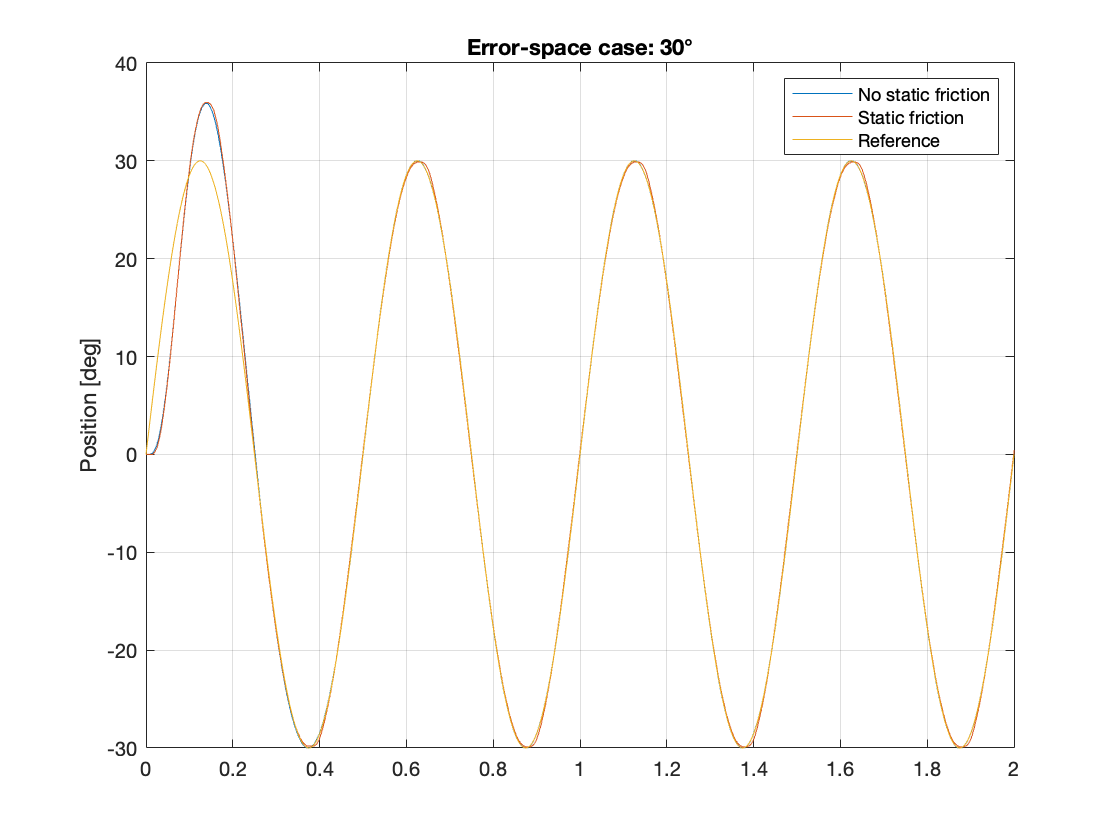

% Open Simulink model
open_system('Simulink/SS_Error_space.slx');

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '2');
% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','30','Frequency','err_space.w3');
set_param('SS_Error_space/switch','sw','1');
set_param('SS_Error_space/switch1','sw','1');
% State-space Controller
set_param('SS_Error_space/State-space Controller/tf','Numerator','err_space.Hnum_3');
set_param('SS_Error_space/State-space Controller1/tf','Numerator','err_space.Hnum_3');
set_param('SS_Error_space/State-space Controller/tf','Denominator','err_space.Hden_3');
set_param('SS_Error_space/State-space Controller1/tf','Denominator','err_space.Hden_3');
set_param('SS_Error_space/State-space Controller/k','Gain','err_space.Kpsi_3','Multiplication','Matrix(K*u)'); 
set_param('SS_Error_space/State-space Controller1/k','Gain','err_space.Kpsi_3','Multiplication','Matrix(K*u)'); 
% DC motor + gearbox
set_param('SS_Error_space/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('SS_Error_space/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(12);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
%ylim([20,40]);
title('Error-space case: 30°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 60*

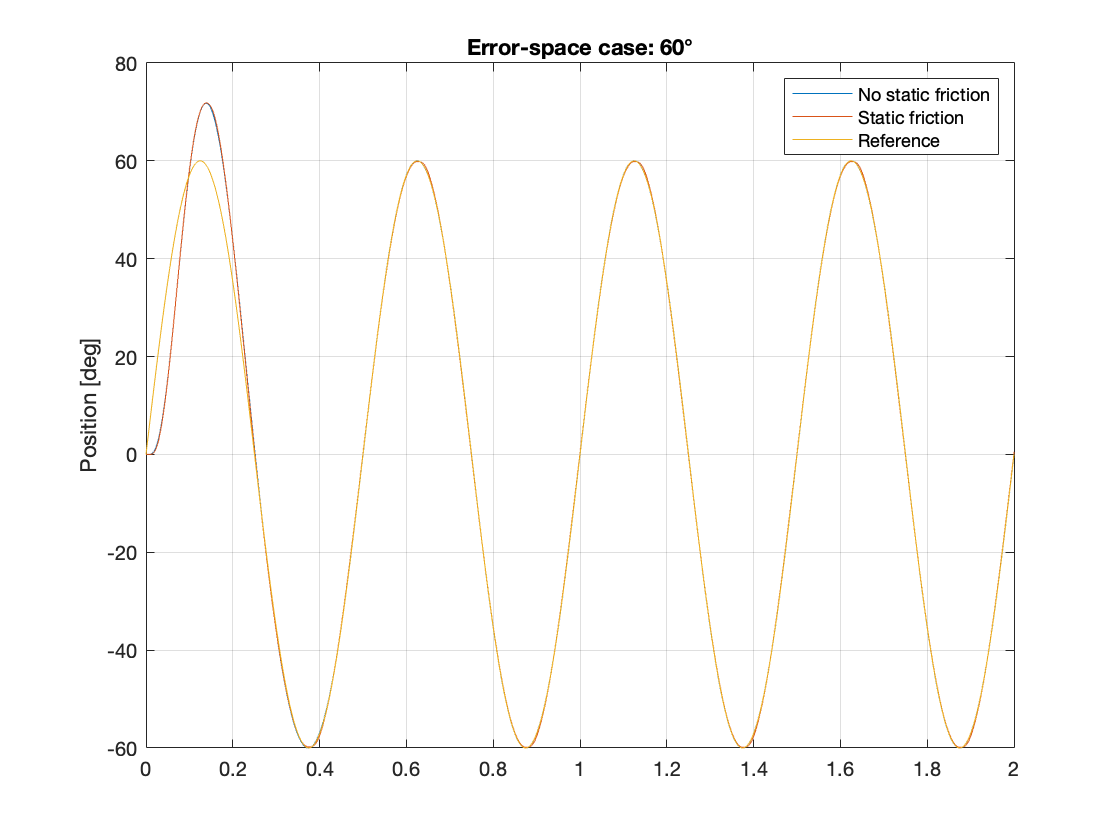

% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','60','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','60','Frequency','err_space.w3');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(13);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: 60°');
legend('No static friction', 'Static friction', 'Reference');

#### Simulation 90*

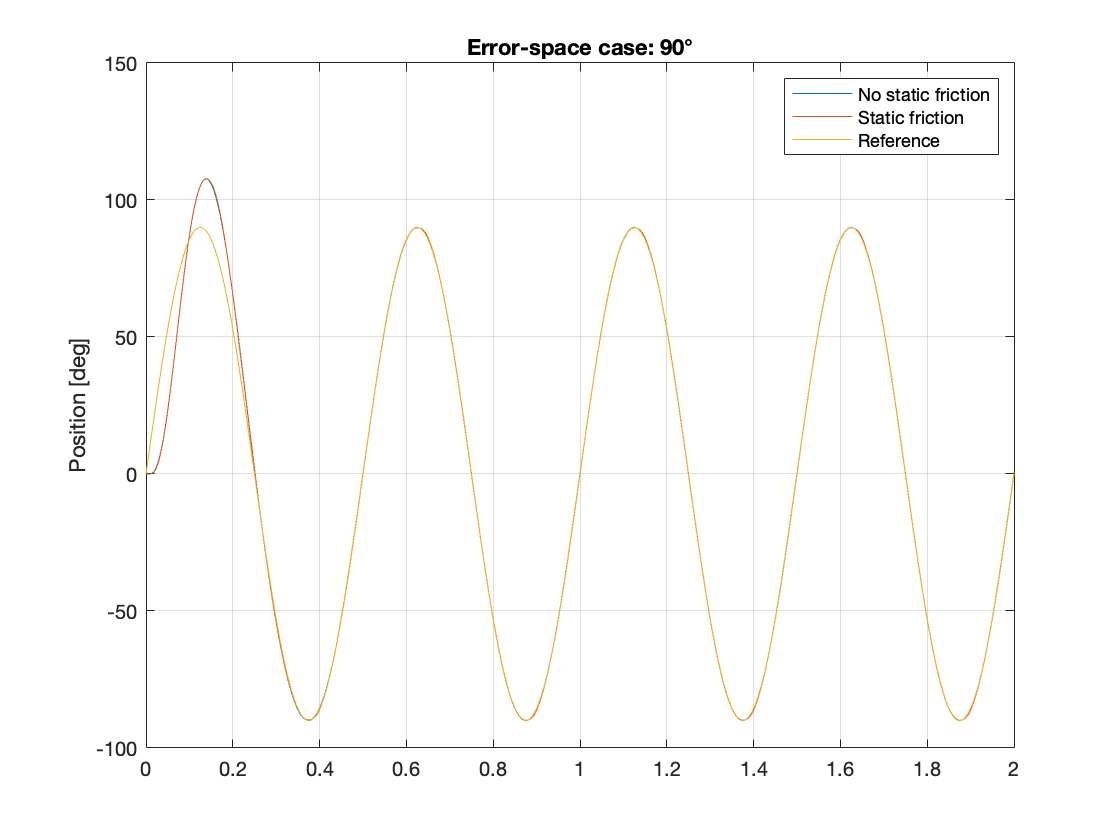

% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','90','Frequency','err_space.w3');
set_param('SS_Error_space/Sine1','Amplitude','90','Frequency','err_space.w3');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(14);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: 90°');
legend('No static friction', 'Static friction', 'Reference');

#### 2.2.7 

#### Simulation (Tracking of sine with T=0.1 with controller K3)

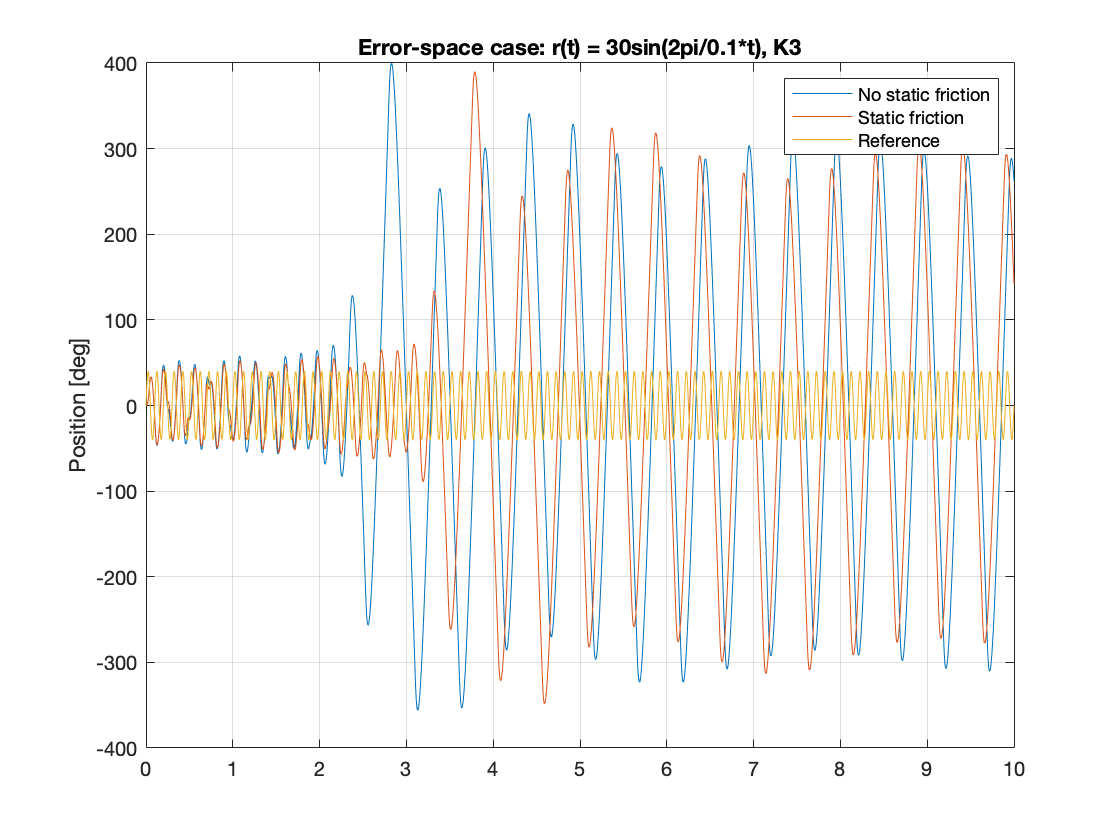

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '10');
% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','40','Frequency','2*pi/0.1');
set_param('SS_Error_space/Sine1','Amplitude','40','Frequency','2*pi/0.1');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(15);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: r(t) = 30sin(2pi/0.1*t), K3');
legend('No static friction', 'Static friction', 'Reference');

#### 2.2.8 

#### Simulation (Tracking of step of amplitude 40° with controller K3)

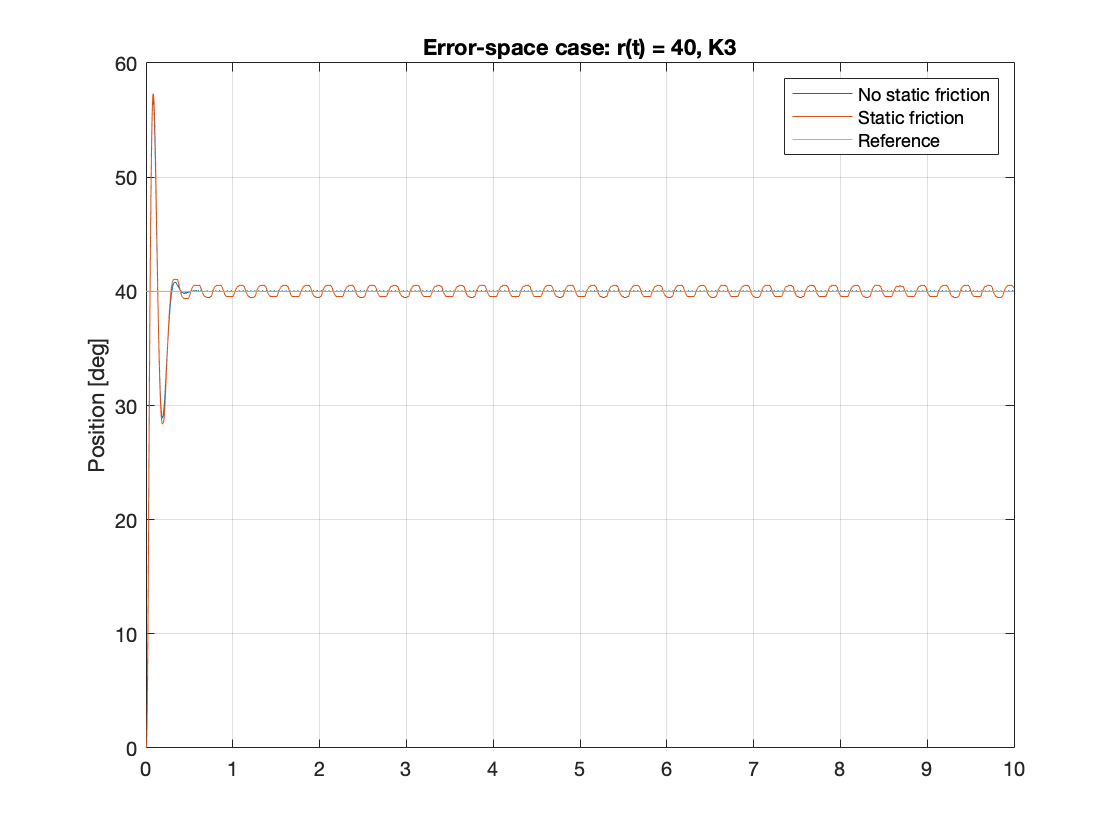

% Set parameters
set_param('SS_Error_space', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '10');
% Ref & Ref1 
set_param('SS_Error_space/Sine','Amplitude','40','Frequency','2*pi/0.1');
set_param('SS_Error_space/Sine1','Amplitude','40','Frequency','2*pi/0.1');
set_param('SS_Error_space/step','Time','0','After','40');
set_param('SS_Error_space/step1','Time','0','After','40');
set_param('SS_Error_space/switch','sw','0');
set_param('SS_Error_space/switch1','sw','0');

% Run simulation
sim('SS_Error_space');

% Extract simulation results
err_space.t = simres.time; % time vector                        
err_space.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
err_space.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
err_space.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(16);
plot(err_space.t, err_space.thl_nsf);
hold on;
plot(err_space.t, err_space.thl_sf);
hold on;
plot(err_space.t, err_space.thl_Ref);
ylabel('Position [deg]');
grid on;
title('Error-space case: r(t) = 40, K3');
legend('No static friction', 'Static friction', 'Reference');

## BODE METHOD

function [kp, ki, kd] = BodMet(w_gc,ph_m,simp_model)
[mag_wgc, phm_wgc] = bode(simp_model.P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end